clearvars
%地上局アンテナ
PtdBm = 65;
PtW = 10^(PtdBm / 10) / 1000;
GtdBi = 0;
Gt = 10^(GtdBi / 10);
NFdBG= 10;
fHz = 2.675* 10^9; 
bw=5e6;
lamdam = 3.0*(10^8) / fHz;
dm = 1000 * 1000;

%衛星
NFdBS = 10;
antennaaream2 = 0.01;
%GrdBi = 0;
%Gr = 10^(GrdBi / 10);

%自由空間伝搬損失
L = (4*pi*dm/ lamdam) ^ 2;
LdB = 10*log10(L);
LosdB = 20* log10(dm) + 20*log10(fHz) -147.6

LosdB = 160.9465


eta = 0.5; %開口効率

% for antnum = 1:1:50000
   A = antennaaream2;
   Gr = (4 * pi / lamdam^2) * eta * A;
   GrdBi = 10 *log10(Gr);
   TempK = 300;
   k = 1.38e-23;
   NoiseW = k * TempK * bw * NFdBS;
   NoisedBW = 10 * log10(NoiseW);
    
   %受信電力
    PdBm = PtdBm+ GtdBi - LdB + GrdBi;
    PW = 10 ^ (PdBm / 10) / 1000;
    CNR = (PW * (10000)^2) / (NoiseW * 10000);
    CNRdB = 10*log10(CNR);
% end

% plot(PdB)
% xlabel("アンテナ個数")
% ylabel("衛星受信電力[dBm]")
% plot(CNRdB)

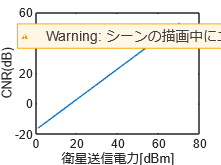

for PtdBm = 1:1:70
    PtW = 10^(PtdBm / 10) / 1000;

    %受信電力
    PdBm(PtdBm) = PtdBm+ GtdBi - LdB + GrdBi;
    PW(PtdBm) = 10 .^ (PdBm(PtdBm) / 10) / 1000;
    CNR(PtdBm) = (PW(PtdBm) * (10000)^2) / (NoiseW * 10000);
    CNRdB(PtdBm) = 10*log10(CNR(PtdBm));
end

plot(CNRdB)
xlabel("衛星送信電力[dBm]")
ylabel("CNR(dB)")